# **Uninfected**

## **GLOBULOS BLANCOS**

### **a) Anotaciones**

close all; clc; clearvars;
% Cargar carpeta del 1º paciente
imageFolder='C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\Uninfected\NIH-NLM-ThickBloodSmearsU\Uninfected Patients\TF201_HT6\tiled'; 

% Cargar imagenes del 1º paciente
imageFiles=dir(fullfile(imageFolder, '*.tiff'));

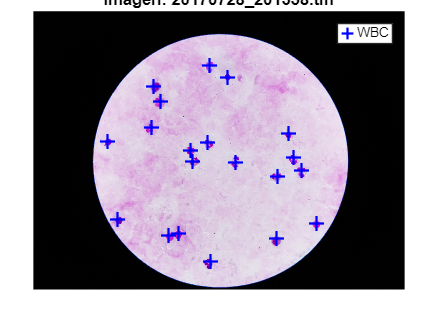

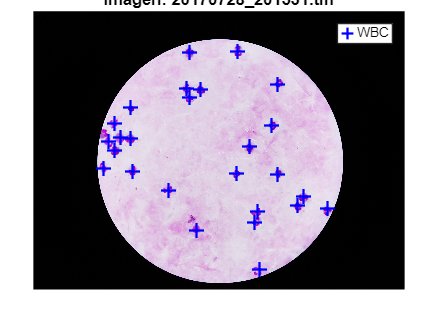

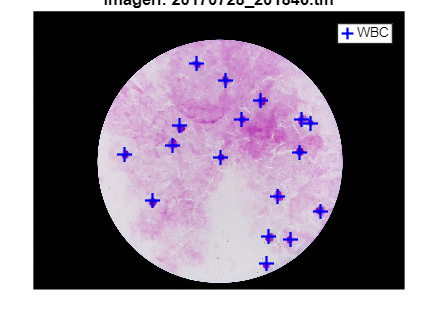

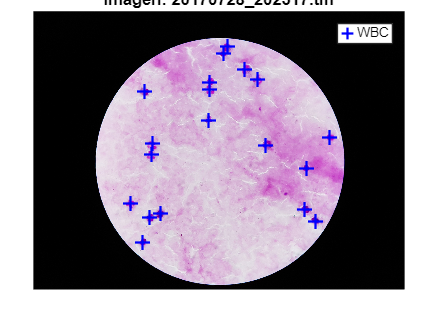

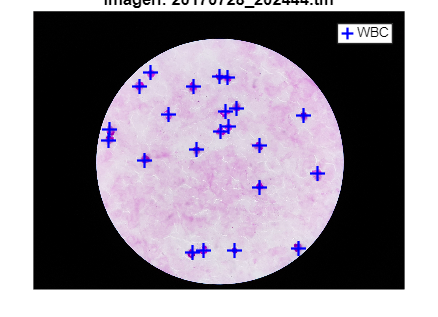

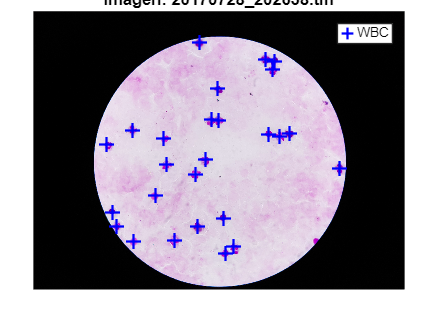

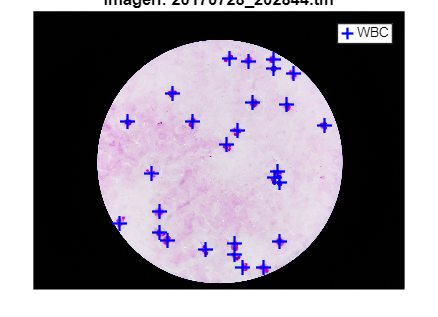

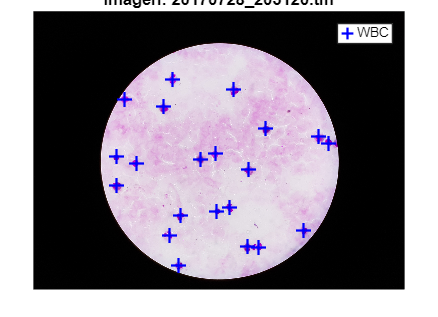

for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    figure;
    imshow(I); hold on;

    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\Uninfected\NIH-NLM-ThickBloodSmearsU\Annotations\TF201_HT6\results\2546', [imageFiles(i).name(1:end-5), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== GLÓBULOS BLANCOS =====
    solo_WBC = datos(strcmp(datos.Var2, 'White_Blood_Cell'), :);
    x_wbc = solo_WBC.Var6;
    y_wbc = solo_WBC.Var7;
    plot(x_wbc, y_wbc, 'b+', 'MarkerSize', 10, 'LineWidth', 1.5);  % cruces azules

    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    legend('WBC');
    hold off;
end

### **b) 2º Modelo Otsu**

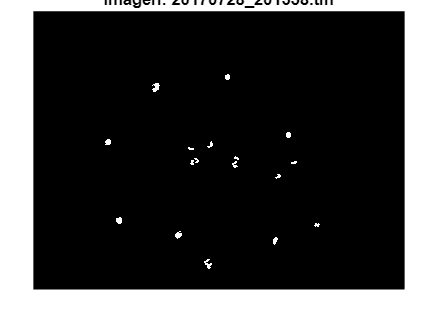

numero_de_wbc = 20

candidatos_a_wbc = 17

wbc_detectados = 14

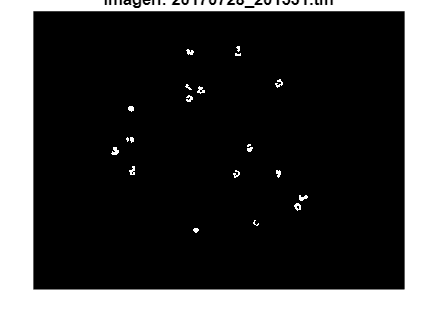

numero_de_wbc = 26

candidatos_a_wbc = 18

wbc_detectados = 17

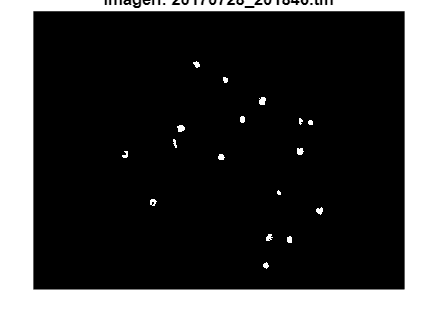

numero_de_wbc = 17

candidatos_a_wbc = 17

wbc_detectados = 17

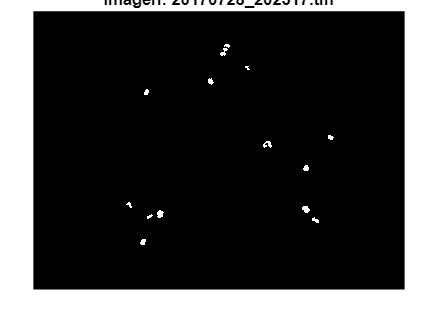

numero_de_wbc = 19

candidatos_a_wbc = 14

wbc_detectados = 14

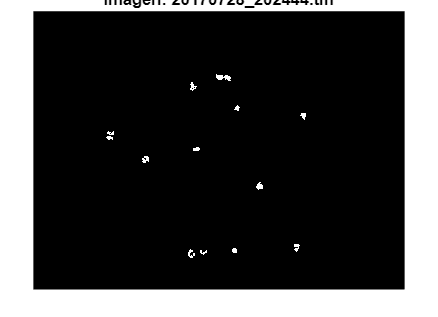

numero_de_wbc = 22

candidatos_a_wbc = 14

wbc_detectados = 14

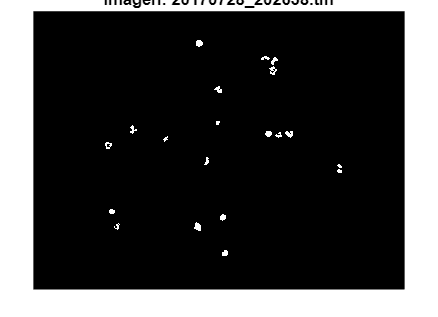

numero_de_wbc = 26

candidatos_a_wbc = 20

wbc_detectados = 19

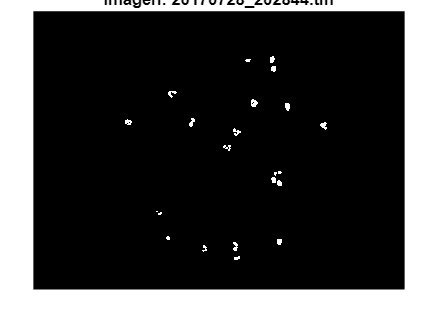

numero_de_wbc = 27

candidatos_a_wbc = 22

wbc_detectados = 20

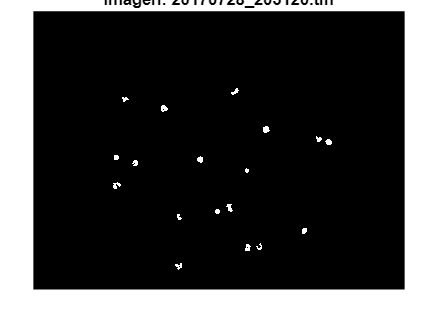

numero_de_wbc = 21

candidatos_a_wbc = 18

wbc_detectados = 18

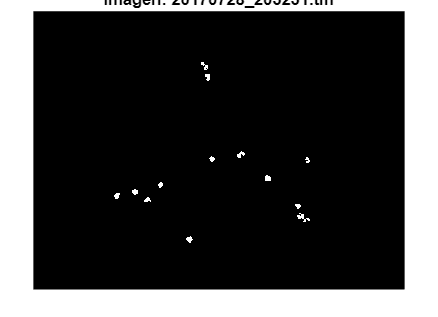

numero_de_wbc = 20

candidatos_a_wbc = 14

wbc_detectados = 14

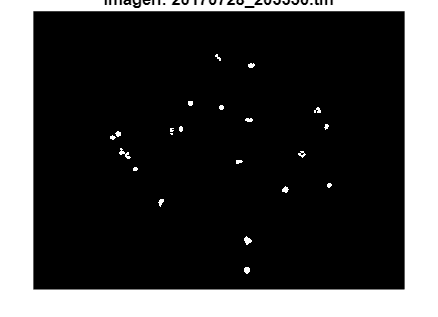

numero_de_wbc = 27

candidatos_a_wbc = 21

wbc_detectados = 21

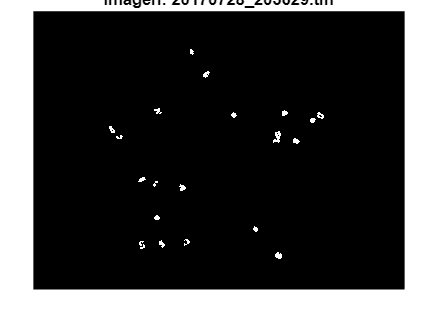

numero_de_wbc = 26

candidatos_a_wbc = 20

wbc_detectados = 20

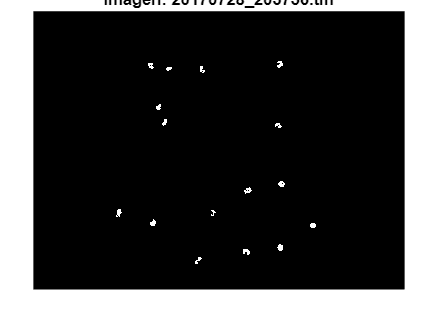

numero_de_wbc = 21

candidatos_a_wbc = 16

wbc_detectados = 16

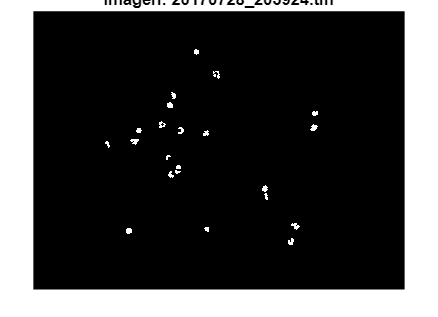

numero_de_wbc = 29

candidatos_a_wbc = 22

wbc_detectados = 21

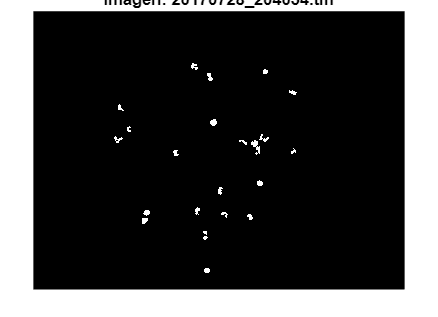

numero_de_wbc = 32

candidatos_a_wbc = 26

wbc_detectados = 23

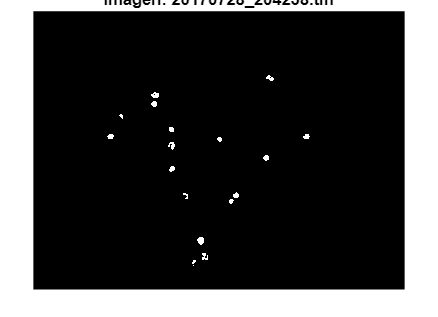

numero_de_wbc = 18

candidatos_a_wbc = 17

wbc_detectados = 17

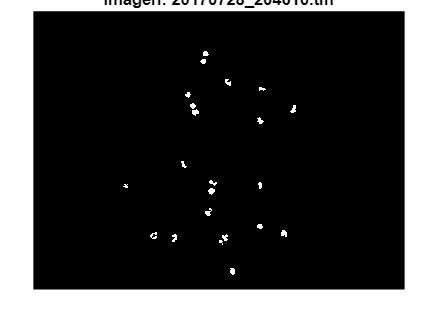

numero_de_wbc = 31

candidatos_a_wbc = 22

wbc_detectados = 21

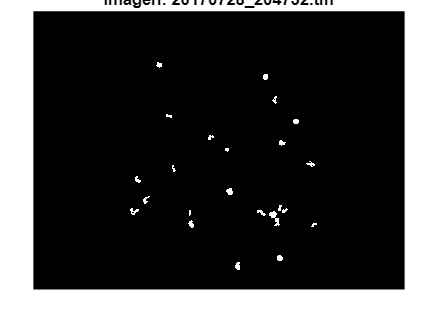

numero_de_wbc = 28

candidatos_a_wbc = 24

wbc_detectados = 23

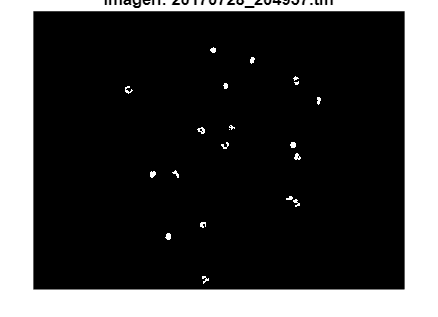

numero_de_wbc = 27

candidatos_a_wbc = 19

wbc_detectados = 18

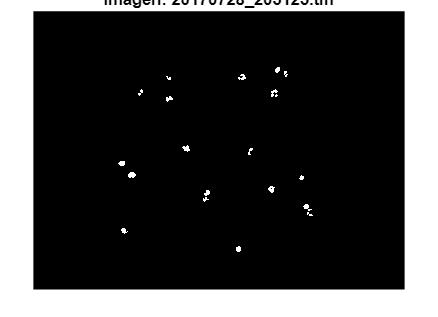

numero_de_wbc = 29

candidatos_a_wbc = 19

wbc_detectados = 19

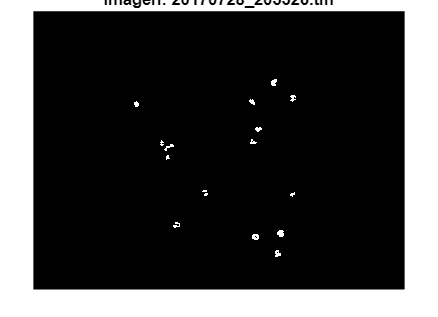

numero_de_wbc = 21

candidatos_a_wbc = 15

wbc_detectados = 14

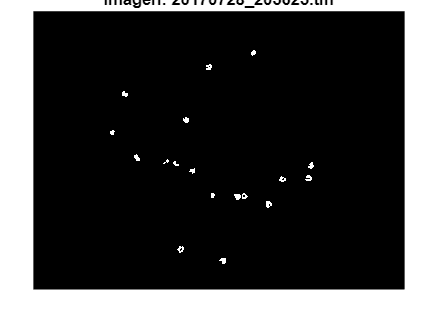

numero_de_wbc = 30

candidatos_a_wbc = 18

wbc_detectados = 18

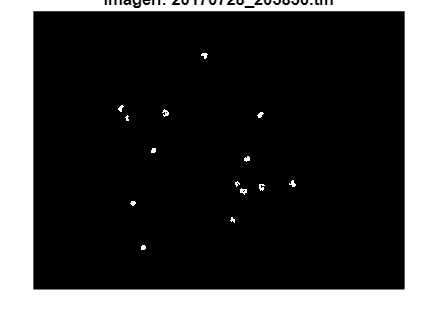

numero_de_wbc = 23

candidatos_a_wbc = 14

wbc_detectados = 13

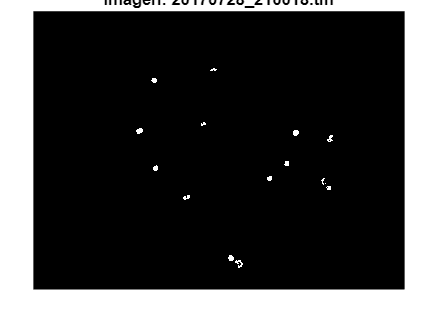

numero_de_wbc = 19

candidatos_a_wbc = 14

wbc_detectados = 14

total_wbc_reales = 0;
total_candidatos = 0;
total_wbc_detectados = 0;
for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I = imread(filename);

    % Binario y escala de grises
    I_gray = im2double(rgb2gray(I));

    % 1. Filtro
    I_sinruido = medfilt2(I_gray, [3 3]);

    % 2. Umbral automático (Otsu)
    umbral = graythresh(I_sinruido) * 0.95;

    % 3. Binarizar
    M1 = imbinarize(I_sinruido, umbral);
    
    % 4. Rellenar agujeros
    M2 = imfill(M1, 'holes');
    
    % 5. Separar glóbulos blancos (restar la máscara binaria original)
    globulos_blancos_ruido = M2 & ~M1;
    
    % 6. Eliminar pequeños ruidos
    globulos_blancos = bwareaopen(globulos_blancos_ruido, 1500);
    
    % Visualizar
    figure;
    imshow(globulos_blancos, [])
    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');

    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\Uninfected\NIH-NLM-ThickBloodSmearsU\Annotations\TF201_HT6\results\2546', [imageFiles(i).name(1:end-5), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== GLÓBULOS BLANCOS =====
    solo_WBC = datos(strcmp(datos.Var2, 'White_Blood_Cell'), :);
    x_wbc = solo_WBC.Var6;
    y_wbc = solo_WBC.Var7;

    % ============Verificar el modelo========
    
    % Extraer el numero de wbc
    tamano=size(solo_WBC);
    numero_de_wbc = tamano(1,1)
    n=8;
    % Candidatos a wbc
    CC_2 = bwconncomp(globulos_blancos,n);
    properties_2 = {'Centroid', 'Circularity', 'Area','Eccentricity', 'Solidity'};
    caracteristicas = regionprops(CC_2,properties_2);
    tamano=size(caracteristicas);
    candidatos_a_wbc=tamano(1,1)

    % wbc detectados
    umbral_distancia = 50;
    wbc_detectados = 0;

    % Lista para guardar cuáles detecciones ya fueron usadas
    detectados_usados = false(length(caracteristicas), 1);

    % Recorrer cada wbc real
    for p = 1:length(x_wbc)
        centro_real = [x_wbc(p), y_wbc(p)];
        for d = 1:length(caracteristicas)
            if detectados_usados(d)
            continue;  % Saltar si esta detección ya fue usada
            end
            centro_detectado = caracteristicas(d).Centroid;
            distancia = norm(centro_real - centro_detectado);
            if distancia < umbral_distancia
                wbc_detectados = wbc_detectados + 1;
                detectados_usados(d) = true;
                break;  % Evita contar un wbc detectado más de una vez
            end
        end
    end
    % Mostrar wbc detectados
    wbc_detectados

    % Sumas de los wbc reales, candidatos y detectados 
    total_wbc_reales = total_wbc_reales + numero_de_wbc;
    total_candidatos = total_candidatos + candidatos_a_wbc;
    total_wbc_detectados = total_wbc_detectados + wbc_detectados;
end


% Analizar modelo con estos resultados
total_wbc_reales

total_wbc_reales = 559

total_candidatos

total_candidatos = 421

total_wbc_detectados

total_wbc_detectados = 405


% Confusion matrix
TP=total_wbc_detectados;
FP=total_candidatos-total_wbc_detectados;
FN=total_wbc_reales-total_wbc_detectados;

sensitivity=(TP/(TP+FN))*100

sensitivity = 72.4508

precision=(TP/(TP+FP))*100

precision = 96.1995